GPU Check

gpuDeviceTable

ans = 1×5 table
    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      


Set GPU

%% gpuDevice(1)

Parameters

name = "AlexNet"

name = "AlexNet"

dataset_size = 2000

dataset_size = 2000

batch_size = 40

batch_size = 40

epochs = 10

epochs = 10

model_directory = strcat("CNN/", name, "/MathLab_Data")

model_directory = "CNN/AlexNet/MathLab_Data"

mkdir(model_directory)

mkdir(model_directory + "/training")

mkdir(model_directory + "/validation")

mkdir(model_directory + "/final_test_results")

Loading dataset

files = dir();
file_names = {files.name};

if any(file_names(:) == "Mushroom dataset") == 0
    disp("Dataset file not found, unzipping...")
    unzip("Mushroom dataset.zip", "Mushroom dataset/")
    disp("Done")
else
    disp("Dataset file found")
end

Dataset file found



disp("Loading dataset files...")

Loading dataset files...


src_folder = "Mushroom dataset/cnn";
dataset = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");
disp("Done")

Done



classNames = categories(dataset.Labels)

classNames = 2×1 cell array
    {'Edible'   }
    {'Poisonous'}


numClasses = numel(classNames);

K Group Partition

k_groups = cvpartition(dataset_size, "KFold", 10)

k_groups = K-fold cross validation partition
   NumObservations: 2000
       NumTestSets: 10
         TrainSize: 1800  1800  1800  1800  1800  1800  1800  1800  1800  1800
          TestSize: 200  200  200  200  200  200  200  200  200  200
          IsCustom: 0

Mean accuracy setup

acc_history = zeros(1, 10)

acc_history =      0     0     0     0     0     0     0     0     0     0


Train network with K-Groups

for i = 1:(k_groups.NumTestSets)

    disp("K : " + i)

    k_train_index = training(k_groups, i);
    k_test_index = test(k_groups, i);

    dataset_train = imageDatastore(dataset.Files(k_train_index), "Labels", dataset.Labels(k_train_index));
    dataset_val = imageDatastore(dataset.Files(k_test_index), "Labels", dataset.Labels(k_test_index));

    net = imagePretrainedNetwork("alexnet", NumClasses=numClasses);
    options = trainingOptions("sgdm", ...
        MiniBatchSize=batch_size, ...
        MaxEpochs=epochs, ...
        Metrics="accuracy", ...
        InitialLearnRate=1e-3, ...
        ValidationFrequency=1, ...
        Verbose=0, ...
        ValidationData=dataset_val, ...
        Plots="training-progress");

    [net, info]= trainnet(dataset_train, net, "crossentropy", options);
    acc_column = info.TrainingHistory(:, 5);
    acc_history(i) = table2array(acc_column(end, :))
    
    train = info.TrainingHistory;
    writetable(train, model_directory + "/training" + "/train" + "K" + i + ".csv");

    val = info.ValidationHistory;
    writetable(val, model_directory + "/validation" + "/val" + "K" + i + ".csv");

end

K : 1


Load final train, test set

files = dir();
file_names = {files.name};

if any(file_names(:) == "FinalTrainTestSet") == 0
    disp("Final dataset file not found, unzipping...")
    unzip("FinalTrainTestSet.zip", "FinalTrainTestSet/")
    disp("Done")
else
    disp("Final dataset file found")
end

Final dataset file found



disp("Loading final dataset train...")

Loading final dataset train...



src_folder = "FinalTrainTestSet/dataset_train/cnn";
final_dataset_train = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

disp("Loading final dataset test...")

Loading final dataset test...



src_folder = "FinalTrainTestSet/dataset_test/cnn";
final_dataset_test = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

disp("Done")

Done


Train model

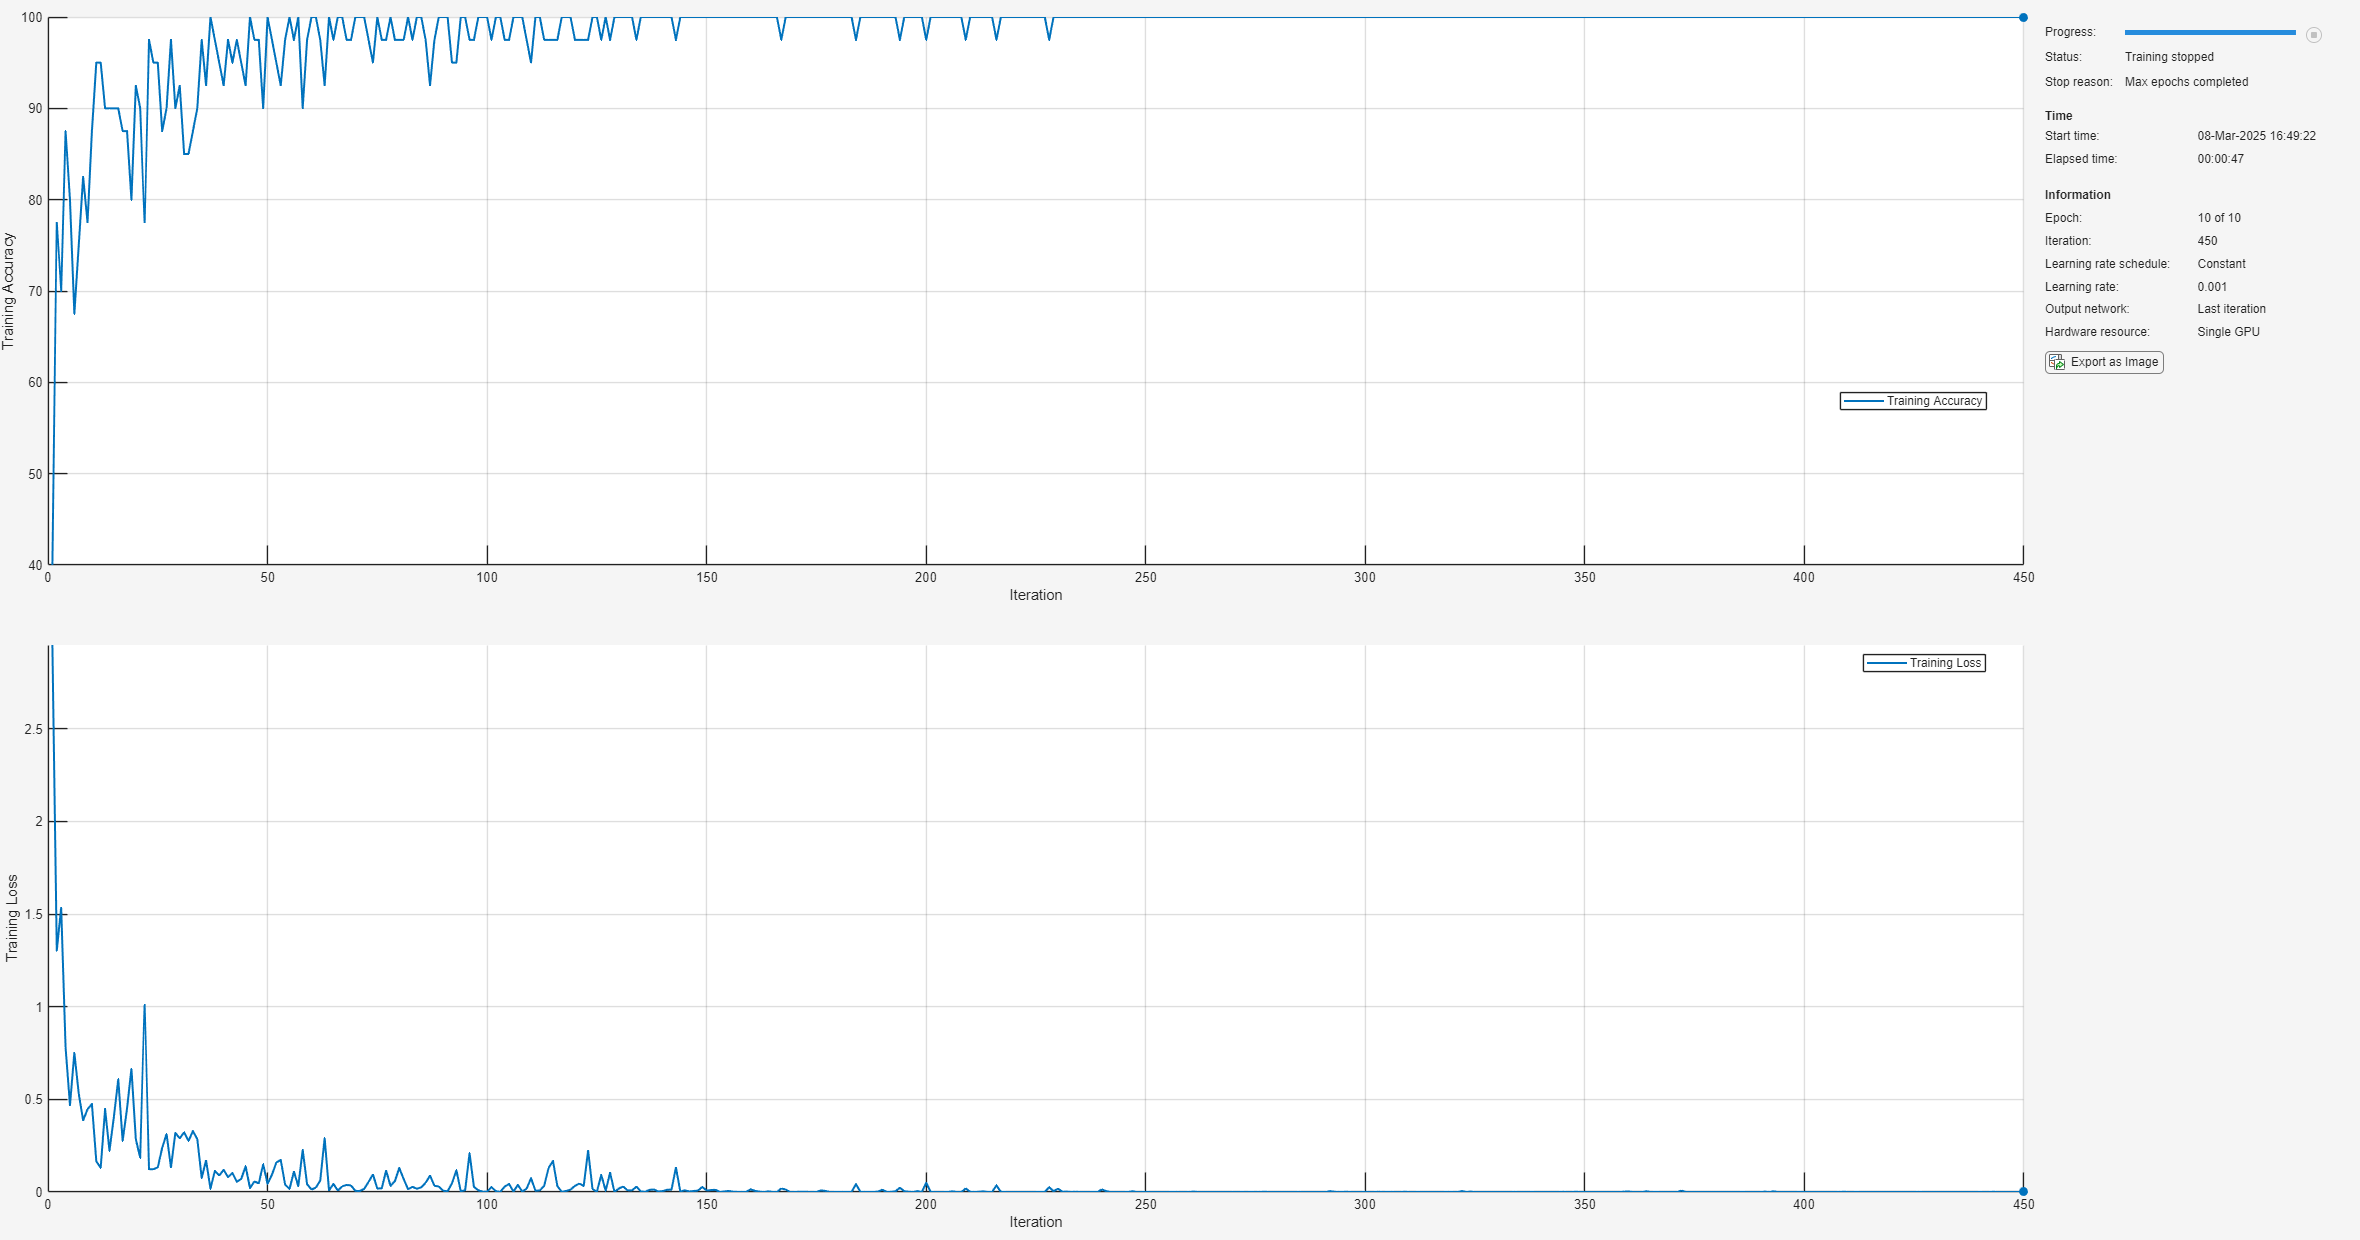

net = imagePretrainedNetwork("alexnet", NumClasses=numClasses);
    options = trainingOptions("sgdm", ...
        MiniBatchSize=batch_size, ...
        MaxEpochs=epochs, ...
        Metrics="accuracy", ...
        InitialLearnRate=1e-3, ...
        Verbose=0, ...
        Plots="training-progress");

[net, info]= trainnet(final_dataset_train, net, "crossentropy", options);

Time : 45s

Compute predictions

scores = minibatchpredict(net, final_dataset_test);

scores = 200×2 single matrix
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    0.9999    0.0001
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000


y_predicted = scores2label(scores, classNames)

y_predicted = 200×1 categorical array
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 


y_test = final_dataset_test.Labels

Export predictions

pred = array2table(y_predicted);

pred = 200×1 table
    y_predicted
    ___________

      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   
      Edible   


test = array2table(y_test);

test = 200×1 table
    y_test
    ______

    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible
    Edible



disp("Exporting final results...")

writetable(pred, model_directory + "/final_test_results/y_predicted.csv");
writetable(test, model_directory + "/final_test_results/y_test.csv");

disp("Done")

Deep dreaming

layer = "fc7";
channels = 1:16;

I = deepDreamImage(net, layer, channels, ...
    PyramidLevels=6, ...
    Verbose=1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.08 |               1 |
|           2 |         1.46 |               1 |
|           3 |         1.62 |               1 |
|           4 |         5.20 |               1 |
|           5 |        10.10 |               1 |
|           6 |        14.65 |               1 |
|           7 |        19.66 |               1 |
|           8 |        26.35 |               1 |
|           9 |        30.32 |               1 |
|          10 |        35.66 |               1 |
|           1 |         6.77 |               2 |
|           2 |         6.89 |               2 |
|           3 |         8.17 |               2 |
|           4 |        14.64 |               2 |
|           5 |         9.70 |               2 |
|           6 |        15.89 |               2 |
|           7 |     

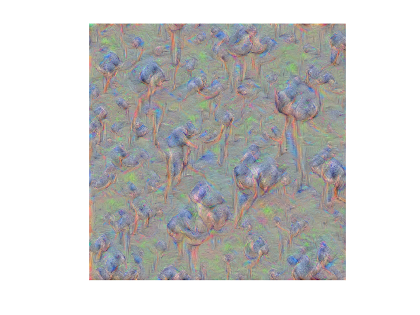

imshow(I(:,:,:,9))

imwrite(I(:,:,:,9), "CNN/" + name + "/" + "DP3.png")